# Neural Network

Our neural network is shown in Figure. It has 3 layers – an input layer, a hidden layer and an output layer. 

Inputs are pixel values of digit images. Since the images are of size 20 *× *20, this gives us 400 input layer units (not counting the extra bias unit which always outputs +1).

The parameters have dimensions that are sized for a neural network with 25 units in the second layer and 10 output units (corresponding to the 10 digit classes).

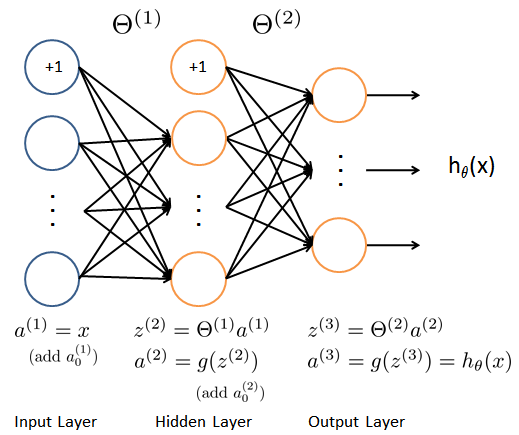

## 1 Initialization

clear; 
close all; 
clc;
input_layer_size  = 400;  % 20x20 Input Images of Digits
hidden_layer_size = 25;   % 25 hidden units
num_labels = 10;          % 10 labels, from 1 to 10

## 2 Loading and Visualizing Data

load('ex4data1.mat');
m = size(X, 1);
sel = randperm(size(X, 1));
sel = sel(1:100);
displayData(X(sel, :));

## 3 Initializing Pameters

initial_Theta1 = randInitializeWeights(input_layer_size, hidden_layer_size);
initial_Theta2 = randInitializeWeights(hidden_layer_size, num_labels);
% Unroll parameters
initial_nn_params = [initial_Theta1(:) ; initial_Theta2(:)];

## 4 Check gradients

%  Check gradients by running checkNNGradients
lambda = 3;
checkNNGradients(lambda);

   -0.0093   -0.0093
    0.0089    0.0089
   -0.0084   -0.0084
    0.0076    0.0076
   -0.0067   -0.0067
   -0.0168   -0.0168
    0.0394    0.0394
    0.0593    0.0593
    0.0248    0.0248
   -0.0327   -0.0327
   -0.0602   -0.0602
   -0.0320   -0.0320
    0.0249    0.0249
    0.0598    0.0598
    0.0386    0.0386
   -0.0174   -0.0174
   -0.0576   -0.0576
   -0.0452   -0.0452
    0.0091    0.0091
    0.0546    0.0546
    0.3145    0.3145
    0.1111    0.1111
    0.0974    0.0974
    0.1187    0.1187
    0.0000    0.0000
    0.0337    0.0337
    0.2040    0.2040
    0.1171    0.1171
    0.0755    0.0755
    0.1257    0.1257
   -0.0041   -0.0041
    0.0170    0.0170
    0.1763    0.1763
    0.1131    0.1131
    0.0862    0.0862
    0.1323    0.1323
   -0.0045   -0.0045
    0.0015    0.0015

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your backpropagation implementation is correct, then 
the relative difference will be

## 5 Training NN

options = optimset('MaxIter', 100);
lambda = 1;
costFunction = @(p) nnCostFunction(p, ...
                                   input_layer_size, ...
                                   hidden_layer_size, ...
                                   num_labels, X, y, lambda);

[nn_params, cost] = fmincg(costFunction, initial_nn_params, options);

Iteration     1 | Cost: 3.287122e+00
Iteration     2 | Cost: 3.238545e+00
Iteration     3 | Cost: 3.204535e+00
Iteration     4 | Cost: 3.138708e+00
Iteration     5 | Cost: 2.484807e+00
Iteration     6 | Cost: 2.278047e+00
Iteration     7 | Cost: 2.057029e+00
Iteration     8 | Cost: 1.747490e+00
Iteration     9 | Cost: 1.693938e+00
Iteration    10 | Cost: 1.624258e+00
Iteration    11 | Cost: 1.490882e+00
Iteration    12 | Cost: 1.374389e+00
Iteration    13 | Cost: 1.227921e+00
Iteration    14 | Cost: 1.178000e+00
Iteration    15 | Cost: 1.149465e+00
Iteration    16 | Cost: 1.015118e+00
Iteration    17 | Cost: 9.871133e-01
Iteration    18 | Cost: 9.718666e-01
Iteration    19 | Cost: 9.243284e-01
Iteration    20 | Cost: 8.881834e-01
Iteration    21 | Cost: 8.619978e-01
Iteration    22 | Cost: 8.294529e-01
Iteration    23 | Cost: 7.810892e-01
Iteration    24 | Cost: 7.517230e-01
Iteration    25 | Cost: 7.162070e-01
Iteration    26 | Cost: 6.882084e-01
Iteration    27 | Cost: 6.702861e-01
I

## 6 Visualize Weights

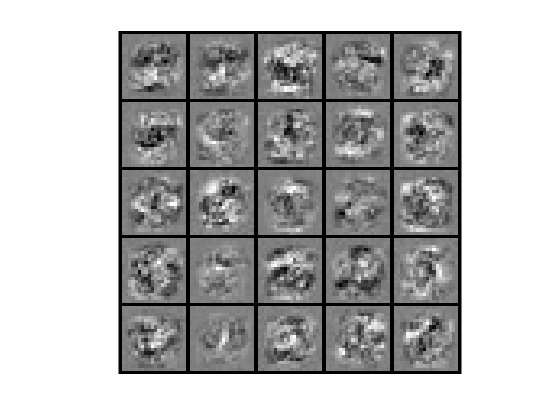

Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), num_labels, (hidden_layer_size + 1));
displayData(Theta1(:, 2:end));

## 7 Implement Predict

pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);


Training Set Accuracy: 98.440000


## 8 Function

function W = randInitializeWeights(L_in, L_out)
%RANDINITIALIZEWEIGHTS Randomly initialize the weights of a layer with L_in
%incoming connections and L_out outgoing connections
%   W = RANDINITIALIZEWEIGHTS(L_in, L_out) randomly initializes the weights 
%   of a layer with L_in incoming connections and L_out outgoing 
%   connections. 
%
%   Note that W should be set to a matrix of size(L_out, 1 + L_in) as
%   the first column of W handles the "bias" terms
%
    epsilon_init = 0.12;
    W = rand(L_out, 1 + L_in) * 2 * epsilon_init - epsilon_init;
end

function g = sigmoid(z)
%SIGMOID Compute sigmoid functoon
%   J = SIGMOID(z) computes the sigmoid of z.
    g = 1.0 ./ (1.0 + exp(-z));
end

function g = sigmoidGradient(z)
%SIGMOIDGRADIENT returns the gradient of the sigmoid function
%evaluated at z
%   g = SIGMOIDGRADIENT(z) computes the gradient of the sigmoid function
%   evaluated at z. This should work regardless if z is a matrix or a
%   vector. In particular, if z is a vector or matrix, you should return
%   the gradient for each element.
    g = sigmoid(z).*(1-sigmoid(z));
end

function [J, grad] = nnCostFunction(nn_params, ...
                                   input_layer_size, ...
                                   hidden_layer_size, ...
                                   num_labels, ...
                                   X, y, lambda)
%NNCOSTFUNCTION Implements the neural network cost function for a two layer
%neural network which performs classification
%   [J grad] = NNCOSTFUNCTON(nn_params, hidden_layer_size, num_labels, ...
%   X, y, lambda) computes the cost and gradient of the neural network. The
%   parameters for the neural network are "unrolled" into the vector
%   nn_params and need to be converted back into the weight matrices. 
% 
%   The returned parameter grad should be a "unrolled" vector of the
%   partial derivatives of the neural network.

    Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), ...
                     hidden_layer_size, (input_layer_size + 1));
    
    Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), ...
                     num_labels, (hidden_layer_size + 1));
    
    % Setup some useful variables
    m = size(X, 1);
             
    % Part 1: Feedforward the neural network and return the cost in the variable J. 
    a_1 = [ones(m,1) X];
    z_2 = a_1*Theta1';
    a_2 = [ones(m,1) sigmoid(z_2)];
    z_3 = a_2*Theta2';
    a_3 = sigmoid(z_3);
    
    J = 0;
    for k = 1:num_labels
        J = J + (-(y==k)'*log(a_3(:,k))-(1-(y==k)')*log(1-a_3(:,k)))/m;
    end
    J = J + lambda/(2*m)*(sum(Theta1(:,2:end).^2,[1 2]) + sum(Theta2(:,2:end).^2,[1 2]));
    
    
    % Part 2: Implement the backpropagation algorithm to compute the gradients Theta1_grad and Theta2_grad.
    Delta_1 = 0;
    Delta_2 = 0;
    for t = 1:m
        % step1
        a_1 = [1; X(t,:)'];
        z_2 = Theta1*a_1;
        a_2 = [1; sigmoid(z_2)];
        z_3 = Theta2*a_2;
        a_3 = sigmoid(z_3);
    
        % step2
        actual = y(t,:);
        y_k = zeros(num_labels, 1);
        y_k(actual) = 1;
        delta_3 = a_3 - y_k;
    
        % step3
        delta_2 = Theta2'*delta_3.*sigmoidGradient([1;z_2]);
        delta_2 = delta_2(2:end);
    
        % step4
        Delta_1 = Delta_1 + delta_2*a_1';
        Delta_2 = Delta_2 + delta_3*a_2';
    end
    % step5
    Theta1_grad = (1/m) * Delta_1 + lambda/m*Theta1;
    Theta1_grad(:,1) = (1/m) * Delta_1(:,1);
    Theta2_grad = (1/m) * Delta_2 + lambda/m*Theta2;
    Theta2_grad(:,1) = (1/m) * Delta_2(:,1);
    grad = [Theta1_grad(:) ; Theta2_grad(:)];
end

function p = predict(Theta1, Theta2, X)
%PREDICT Predict the label of an input given a trained neural network
%   p = PREDICT(Theta1, Theta2, X) outputs the predicted label of X given the
%   trained weights of a neural network (Theta1, Theta2)
    m = size(X, 1);
    h1 = sigmoid([ones(m, 1) X] * Theta1');
    h2 = sigmoid([ones(m, 1) h1] * Theta2');
    [~, p] = max(h2, [], 2);
end

function checkNNGradients(lambda)
%CHECKNNGRADIENTS Creates a small neural network to check the
%backpropagation gradients
%   CHECKNNGRADIENTS(lambda) Creates a small neural network to check the
%   backpropagation gradients, it will output the analytical gradients
%   produced by your backprop code and the numerical gradients (computed
%   using computeNumericalGradient). These two gradient computations should
%   result in very similar values.
%

    if ~exist('lambda', 'var') || isempty(lambda)
        lambda = 0;
    end
    
    input_layer_size = 3;
    hidden_layer_size = 5;
    num_labels = 3;
    m = 5;
    
    % We generate some 'random' test data
    Theta1 = debugInitializeWeights(hidden_layer_size, input_layer_size);
    Theta2 = debugInitializeWeights(num_labels, hidden_layer_size);
    % Reusing debugInitializeWeights to generate X
    X  = debugInitializeWeights(m, input_layer_size - 1);
    y  = 1 + mod(1:m, num_labels)';
    
    % Unroll parameters
    nn_params = [Theta1(:) ; Theta2(:)];
    
    % Short hand for cost function
    costFunc = @(p) nnCostFunction(p, input_layer_size, hidden_layer_size, ...
                                   num_labels, X, y, lambda);
    
    [cost, grad] = costFunc(nn_params);
    numgrad = computeNumericalGradient(costFunc, nn_params);
    
    % Visually examine the two gradient computations.  The two columns
    % you get should be very similar. 
    disp([numgrad grad]);
    fprintf(['The above two columns you get should be very similar.\n' ...
             '(Left-Your Numerical Gradient, Right-Analytical Gradient)\n\n']);
    
    % Evaluate the norm of the difference between two solutions.  
    % If you have a correct implementation, and assuming you used EPSILON = 0.0001 
    % in computeNumericalGradient.m, then diff below should be less than 1e-9
    diff = norm(numgrad-grad)/norm(numgrad+grad);
    
    fprintf(['If your backpropagation implementation is correct, then \n' ...
             'the relative difference will be small (less than 1e-9). \n' ...
             '\nRelative Difference: %g\n'], diff);

end